# The effect of the gravity on longitudinal vehicle motion

Study the effect of the gravitational force on the longitudinal motion of a road vehicle.

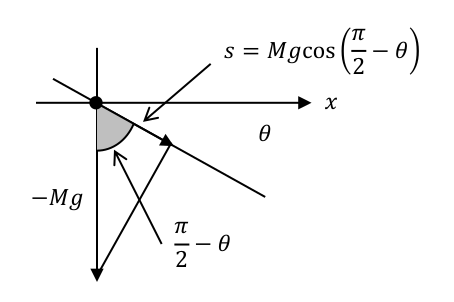

Use example parameters as follows.

% Vehicle mass
M_veh = simscape.Value(1500, "kg");

% Gravitational acceleration
g_accel = simscape.Value(9.81, "m/s^2");

The value of "1G" in Newtons.

Mg = convert(M_veh*g_accel, "N")

Mg =        14715 (N)


Consider the following road grade cases.

road_grade_percent = [0, 5, 10, 20, 35];
road_angle_rad = atan(road_grade_percent/100);
rad2deg(road_angle_rad)

ans =          0    2.8624    5.7106   11.3099   19.2900


inclination_ratio = cos(pi/2 - road_angle_rad)

inclination_ratio =     0.0000    0.0499    0.0995    0.1961    0.3304


F_gravity = Mg*inclination_ratio

F_gravity =    1.0e+03 *

    0.0000    0.7348    1.4642    2.8858    4.8611

    (N)


*Copyright 2026 The MathWorks, Inc.*